# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

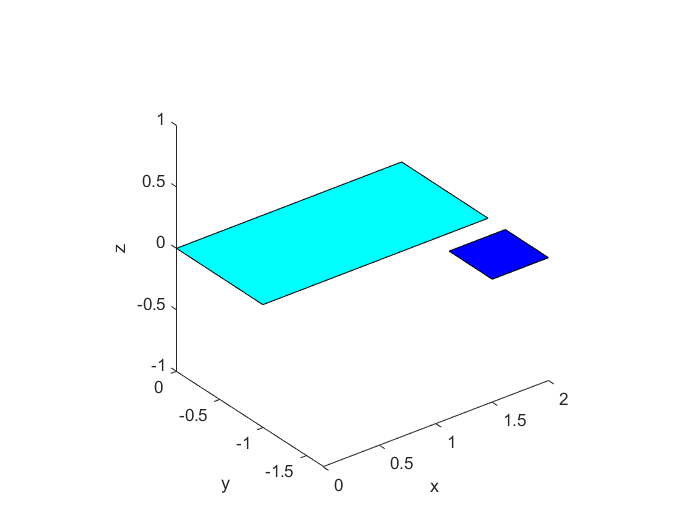

clear;
clf;
clc;
close all;

tableTransform = eye(4);
rotation = eye(4);
translation = eye(4);

% Create the operations table (2 x 1 meters)
matrix = [0 0 0;
          0 2 0;
          1 2 0;
          1 0 0];

operationTable = fill3(matrix(:,1),matrix(:,2),matrix(:,3),'c');
operationTable.Vertices = Transform(operationTable.Vertices, trotz(-pi/2));
hold on;

applyTransform = false;
if applyTransform
    % Rotamos la tabla 10 grados en X y 30 grados en Z
    rotation = trotz(pi/6)*troty(-pi/18);
    operationTableAux = Transform(operationTable.Vertices, rotation);
    translation = transl([10,10,0.8]-operationTableAux(2,:));
    tableTransform = translation*rotation;
end

operationTable.Vertices = Transform(operationTable.Vertices, tableTransform);
% Create the auxiliary table (0.5 x 0.5 meters)
matrix = [1.2 1.5 0;
          1.2   2 0;
          1.7   2 0;
          1.7 1.5 0];
toolTable = fill3(matrix(:,1),matrix(:,2),matrix(:,3),'b');
toolTable.Vertices = Transform(toolTable.Vertices, trotz(-pi/2));
toolTable.Vertices = Transform(toolTable.Vertices, tableTransform);
zlabel('z');ylabel('y');xlabel('x');
axis equal

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

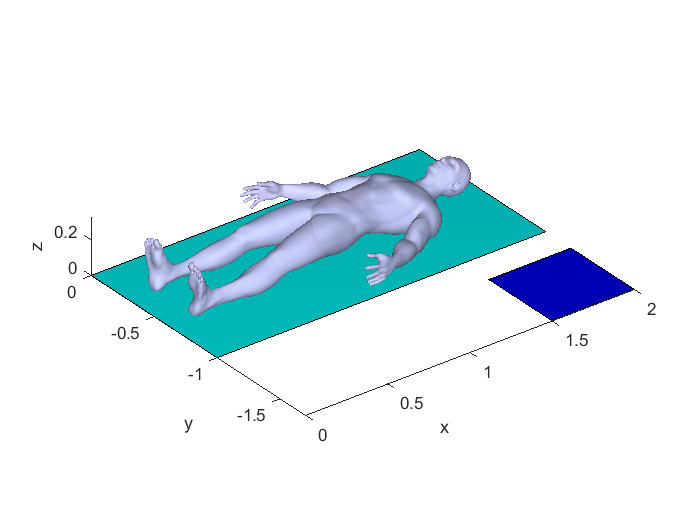

%% put your code Here
HumanBody = load("Model\F_V_Human_Body.mat");

humanYmax = max(HumanBody.V(:, 2));
humanYmin = min(HumanBody.V(:, 2));
HumanBody.V = HumanBody.V / ((humanYmax - humanYmin) / 1.8);
humanXmin = min(HumanBody.V(:, 1));
humanYmax = max(HumanBody.V(:, 2));
humanZmin = min(HumanBody.V(:, 3));
Upperleft = [humanXmin, humanYmax, humanZmin];

HumanBody.V = Transform(HumanBody.V, trotz(-pi/2)*transl([0,1.9,0]-Upperleft));
HumanBody.V = Transform(HumanBody.V, tableTransform);

patch('Faces', HumanBody.F, 'Vertices', HumanBody.V,...
      'FaceColor',[0.8 0.8 1.0],...
      'EdgeColor','none',...
      'FaceLighting',    'gouraud',     ...
      'AmbientStrength', 0.8,'FaceAlpha', 0.8);
camlight('headlight');
material('dull');
axis equal

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

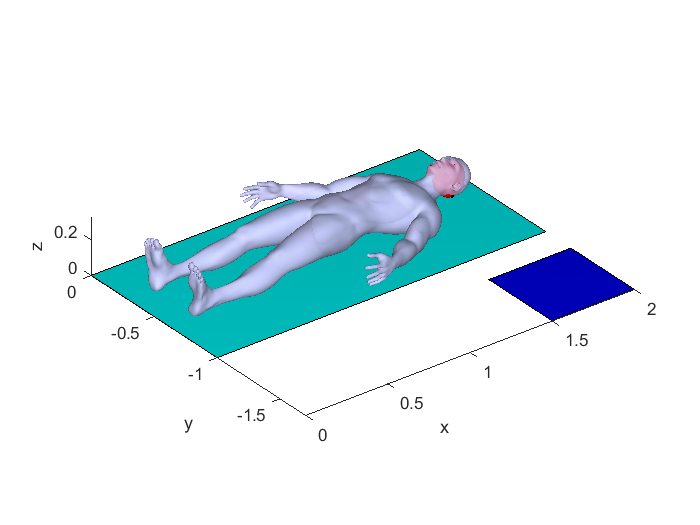

% put your code Here
Skull = load("Model\F_V_N_Skull.mat");

SkullYmax = max(Skull.Ve(:, 2));
SkullYmin = min(Skull.Ve(:, 2));
Skull.Ve = Skull.Ve / ((SkullYmax - SkullYmin) / 0.2);

Skull.Ve = Transform(Skull.Ve, transl([1.68, -0.505, 0.15])*trotz(-pi/2)*trotx(-pi/2));
Skull.Ve = Transform(Skull.Ve, tableTransform);

patch('Faces', Skull.Fa, 'Vertices', Skull.Ve,...
      'FaceColor', 'red' ,...
      'EdgeColor','none');
material('dull');
axis equal

% ------------ Fiducials ----------------
scale = 0.1 / 122; % Tamaño que queremos en eje Y / Tamaño real (185-73)

fiducials = [213 73 32*2; 213 185 65*2; 213 122 94*2];
fiducials = fiducials*scale;
transformacionImg = tableTransform*transl(1.72, -0.615, 0.25)*troty(pi/2);
%transformacionImg = troty(pi/2) * transl(-0.25, -0.615, 1.72)*tableTransform;
fiducials = Transform(fiducials, transformacionImg);

scaleSphere = 1/150;

[X1, Y1, Z1] = sphere;
X1 = X1*scaleSphere+fiducials(1,1); Y1 = Y1*scaleSphere+fiducials(1,2); 
Z1 = Z1*scaleSphere+fiducials(1,3);
surf(X1,Y1,Z1);

[X2, Y2, Z2] = sphere;
X2 = X2*scaleSphere+fiducials(2,1); Y2 = Y2*scaleSphere+fiducials(2,2); 
Z2 = Z2*scaleSphere+fiducials(2,3);
surf(X2,Y2,Z2);

[X3, Y3, Z3] = sphere;
X3 = X3*scaleSphere+fiducials(3,1); Y3 = Y3*scaleSphere+fiducials(3,2);
Z3 = Z3*scaleSphere+fiducials(3,3);
surf(X3,Y3,Z3);
axis equal
axis tight

#### Reference frame a partir del triangulo creado con los fiducials

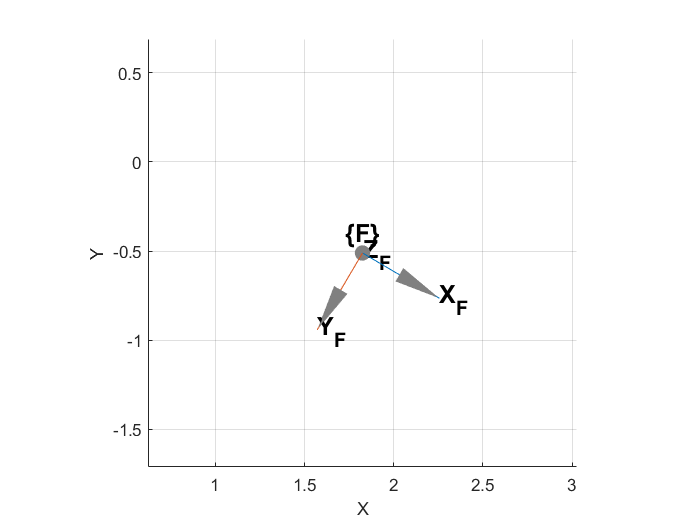

length = 0.5;
width = 1.5;
P = fiducials';
AB=(P(:,1)-P(:,2))/norm(P(:,1)-P(:,2)); 
CB=(P(:,3)-P(:,2))/norm(P(:,2)-P(:,3)); 
A = cross(CB, AB)/norm(cross(CB, AB)); % Approach vector 
RF = oa2r(AB, A); 
center = [mean(P(1,:)), mean(P(2,:)), mean(P(3,:))]'; % Center of the triangle
TF = [RF, center; 0 0 0 1]; 
trplot(TF, ... 
        'frame', 'F', ... 
        'color', 'black',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

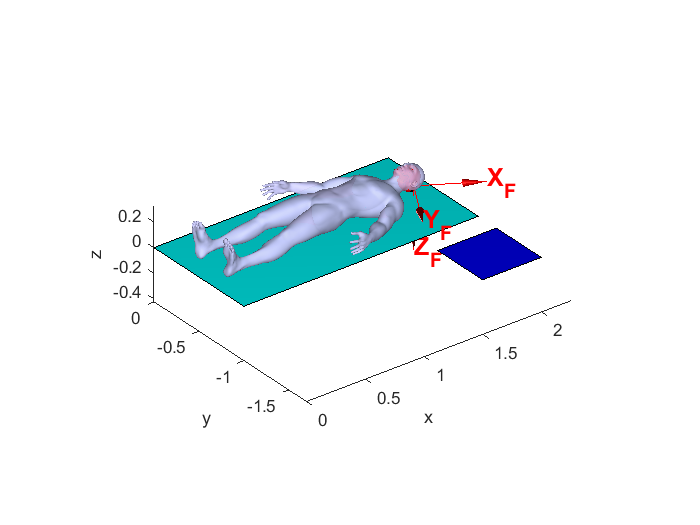

% put your code Here
points = double.empty(0,3);
%figure;
for i = 65:89
    path = cat(2,['DICOM\IMG00'], num2str(i),['.dcm']);
    I = dicomread(path);
    %imshow(I, [])
    BW = imbinarize(mat2gray(I),'adaptive');
    %imshow(BW, [])
    %imshow(filtered, [])
    R = regionprops(BW, 'PixelList','PixelIdxList');
    for j = 1:size(R)
        if ~ismember([129,95],R(j).PixelList,'rows')
            BW(R(j).PixelIdxList) = 0;
        end
    end
    %imshow(filtered)
    se = strel('disk', 3);
    filtered = imopen(BW, se);
    filtered = bwareafilt(filtered,1);
    filtered = imfill(filtered,'holes');
    se = strel('disk', 5);
    filtered = imclose(filtered, se);
    perimetre = bwperim(filtered);
    %imshow(perimetre);
    %imshow(imoverlay(mat2gray(I),perimetre,'yellow'));
    %drawnow;
    %pause(0.1)
    R = regionprops(filtered,'PixelList');
    for j = 1:size(R.PixelList)
        points = [points; [R.PixelList(j,2) R.PixelList(j,1) i*2]];
    end
    %points = [points; 
end
points = points*scale;
T_P_Img = mean(points);
p = Transform(points, transformacionImg);

tumor = patch('XData', p(:,1), 'YData', p(:,2), 'ZData', p(:,3),'FaceColor', 'black' ,...
      'EdgeColor','none');

axis equal
axis tight

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

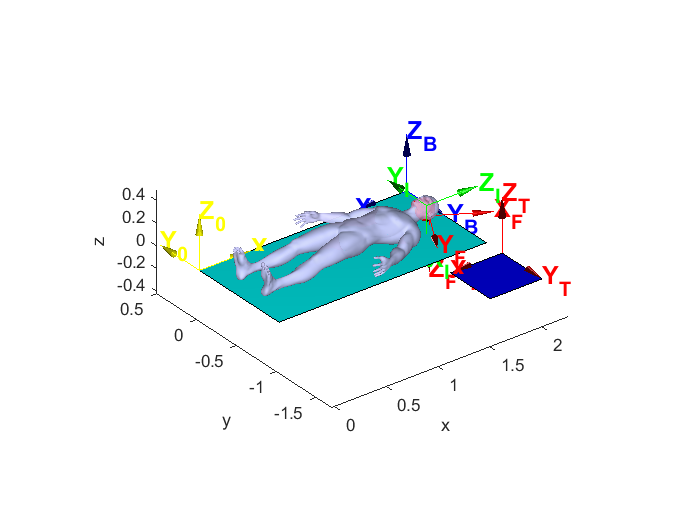

%% put your code Here

% origin (0,0,0)
Z = transl(0,0,0) * tableTransform; 
trplot(Z, ... 
        'frame', '0', ... 
        'color', 'y',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);
    
% Image
I = transformacionImg;
trplot(I, ... 
        'frame', 'I', ... 
        'color', 'g',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);
    
% Body Table 
BT = transl(operationTable.Vertices(2,:))*rotation*trotz(-pi);
trplot(BT, ... 
        'frame', 'B', ... 
        'color', 'b',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);

% Tool Table 
TT = transl(toolTable.Vertices(2,:))*rotation*trotz(-pi);
trplot(TT, ... 
        'frame', 'T', ... 
        'color', 'r',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);


axis tight

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*scale the size of the robot and move near the tumor*

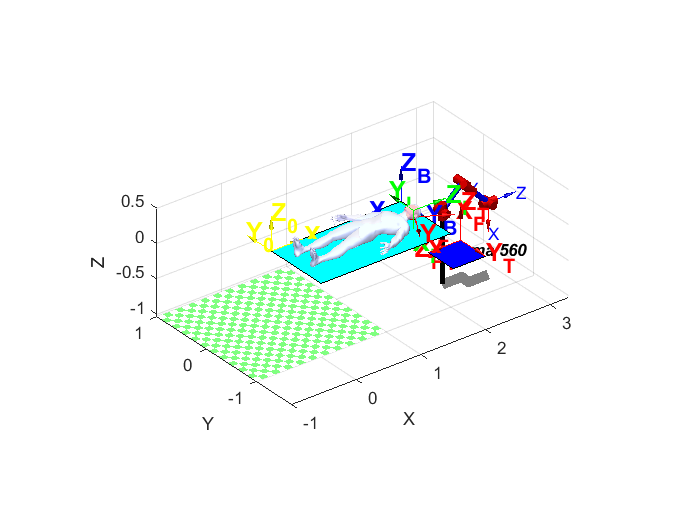

mdl_puma560
base = tableTransform * transl(2.25, -0.5, 0);
p560.base = base;
p560.plot(qn);

% End Efector
E = p560.fkine(qn);
trplot(E, ... 
       'frame', 'E', ... >
       'color', 'k',...
       'arrow',...
       'length', length,...	
       'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
       'width', width);
    
% Robot Base
R = p560.base;
trplot(R, ... 
       'frame', 'R', ... 
       'color', 'm',...
       'arrow',...
       'length', length,...	
       'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
       'width', width);

%set(gca, 'CameraTarget', [0.5, 1 ,0]);
%set(gca, 'CameraPosition', [-4,-10, 8])
axis equal
axis tight

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

E = p560.fkine(qn)

 

E = 
         0         0         1     2.846
         0         1         0   -0.6501
        -1         0         0  -0.01435
         0         0         0         1


Etrasl = E.t

Etrasl =     2.8463
   -0.6501
   -0.0144


Eeul = E.toeul

Eeul =    -0.0000    1.5708   -0.0000


T = SE3(mean(tumor.Vertices))

 

T = 
         1         0         0     1.845
         0         1         0   -0.5063
         0         0         1    0.1694
         0         0         0         1


Ttrasl = T.t

Ttrasl =     1.8454
   -0.5063
    0.1694


Teul = T.toeul

Teul =      0     0     0


T_T_R = transl(Ttrasl-Etrasl)*eul2tr(Teul-Eeul)

T_T_R =    -0.0000         0   -1.0000   -1.0009
         0    1.0000         0    0.1438
    1.0000         0   -0.0000    0.1838
         0         0         0    1.0000


8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

p = Transform(tumor.Vertices, T_T_R);
%scatter3(p(:,1),p(:,2),p(:,3),2);
axis equal
axis tight

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%set(gca, 'CameraTarget', [-2,2,-0.5]);
%set(gca, 'CameraPosition', [-20,2,-0.5]);

%Esto hay que cambiarlo, solo lo puse asi para probar que funcionaba.
steps = 10;
T0 = E.T;
TF = transl(mean(tumor.Vertices));
Q0 = p560.ikine6s(T0);
QF = p560.ikine6s(TF);
t = [0:0.05:4]';
Qn1 = mtraj(@tpoly, Q0, QF, t);
p560.plot(Qn1);

Error using matlab.graphics.primitive.Group/set
Invalid or deleted object.

Error in SerialLink/animate (line 150)
                set(handle, 'UserData', h);

Error in SerialLink/plot (

Qn2 = mtraj(@tpoly, QF, Q0, t);
p560.plot(Qn2);

10.- Prepare a script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here

12.-Modify your code  to repeat point from 7 till 11 if ZX plane of the Robot is not aligned with the plane of symmetry of the human body. There is a free rotation among these two planes. 

*See: * *‘Sckeching_Key_ideas_students.mlx’ and ‘Triangles_2.mlx’ for inspiration.*

*Add your comemnts here.....be concise*

%% put your code Here


function vertex = Transform(vertex, transformation)
    % Function to apply transformations to a matrix where each row is a 3 coordinate point. 
    % Example: 
    % vertex = [0 0 0;
    %           1 1 1]
    % transform = transl(1, 0, 0)
    % result: vertex = [1 0 0;
    %                   2 1 1];
    vertex = [vertex'; ones(1, size(vertex,1))];
    vertex = transformation*vertex;
    vertex = vertex(1:3,:);
    vertex = vertex';
end